# **SS - lab S7 - Zeic Beniamin**

**Exercise 1**

Compute the convolution of the following signals using the analytical method, the graphical method and the function conv.


$$x\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-2\right\rbrack ,y\left\lbrack n\right\rbrack ={0\ldotp 2}^n u\left\lbrack n\right\rbrack$$



$$\begin{array}{l}
x\left\lbrack n\right\rbrack *y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack y\left\lbrack n-k\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\sum_{k=-\infty }^{\infty } \left(u\left\lbrack k\right\rbrack -u\left\lbrack k-2\right\rbrack \right)\;{0\ldotp 2}^{n-k} u\left\lbrack n-k\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\sum_{k=-\infty }^{\infty } u\left\lbrack k\right\rbrack \;{0\ldotp 2}^{n-k} u\left\lbrack n-k\right\rbrack -u\left\lbrack k-2\right\rbrack \;{0\ldotp 2}^{n-k} u\left\lbrack n-k\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\sum_{k=0}^n {0\ldotp 2}^{n-k} u\left\lbrack n\right\rbrack -\sum_{k=2}^n {0\ldotp 2}^{n-k} u\left\lbrack n-2\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={0\ldotp 2}^n \sum_{k=0}^n 5^k \;\;u\left\lbrack n\right\rbrack -{0\ldotp 2}^n \left(\sum_{k=0}^n 5^k -6\;\right)u\left\lbrack n-2\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={0\ldotp 2}^n \;\frac{\left(1-5^{n+1} \right)}{1-5}\;u\left\lbrack n\right\rbrack -{0\ldotp 2}^n \;\frac{\left(25-5^{n+1} \right)}{1-5}\;u\left\lbrack n-2\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{\left(1-5^{n+1} \right)\;u\left\lbrack n\right\rbrack -\left(25-5^{n+1} \right)\;u\left\lbrack n-2\right\rbrack }{-4\left(5^n \right)}\;\\

\end{array}$$


In the avoce obtained equation, we must re-center the two unit step functions (u[n] will become u[n+1] and u[n-2] will become u[n-1]).

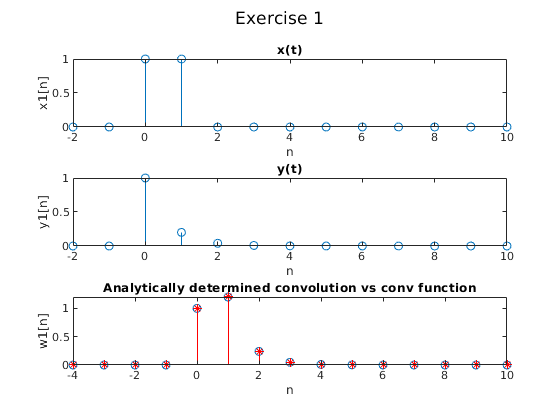

prec = 1;
x1 = @(n) ((n>=0)-(n>=2));
y1 = @(n) (0.2.^n.*(n>=0));
sx1 = -2; ex1 = 10; dtx1 = sx1:prec:ex1;
sy1 = -2; ey1 = 10; dty1 = sy1:prec:ey1;
dtw1 = sx1+sy1:prec:ex1;

w1 = conv(double(x1(dtx1)), y1(dty1));

figure;
sgtitle("Exercise 1")
subplot(3,1,1); stem(dtx1,x1(dtx1)); xlabel('n'); ylabel('x1[n]');
title("x(t)")
subplot(3,1,2); stem(dty1,y1(dty1)); xlabel('n'); ylabel('y1[n]');
title("y(t)")
subplot(3,1,3); stem(dtw1,w1(1:length(dtw1))); xlabel('n'); ylabel('w1[n]'); hold on


title("Analytically determined convolution vs conv function")
% w_calculated = @(n) ((0.2.^n).*6.*(n>=0));
w_calculated = @(n) (((1-5.^(n+1)).*(n>-1) - (25-5.^(n+1)).*(n>1))./(-4*(5.^n)));

stem(dtw1, w_calculated(double(dtw1)), '* r');
hold off;

**Exercise 2**

Let $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack +2\delta \left\lbrack n-1\right\rbrack -\delta \left\lbrack n-3\right\rbrack$ and $h\left\lbrack n\right\rbrack =2\delta \left\lbrack n+1\right\rbrack +2\delta \left\lbrack n-1\right\rbrack$

Compute the convolution of:

i. $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$

ii. $y\left\lbrack n\right\rbrack =x\left\lbrack n+1\right\rbrack *h\left\lbrack n\right\rbrack$

iii. $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n+2\right\rbrack$

Represent graphically in Matlab the signals and their convolutions.

Subpoint A

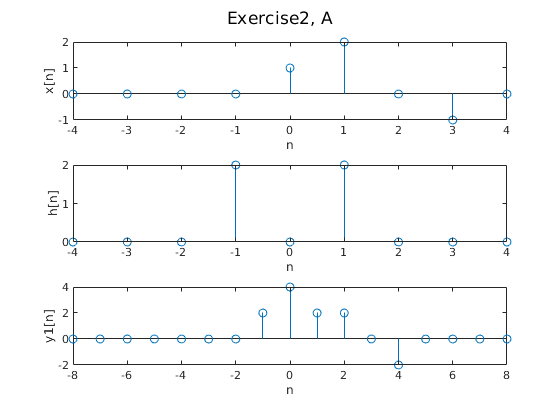

% Subpoint A
t = -4:1:4;
% Define x[n] and h[n] as an anonymous functions
% Use eq to simulate the Kronecker-delta function
x_func = @(n) (eq(n,0)+2*eq(n-1,0)-eq(n-3,0));
h_func = @(n) (2*eq(n+1,0)+2*eq(n-1,0));
% Obtain the signal x[n] for the timespan defined in "t"
x = x_func(t);
h = h_func(t);

y1 = conv(x, h);

figure
sgtitle("Exercise2, A");
subplot(3,1,1); stem(t, x); xlabel('n'); ylabel('x[n]');
subplot(3,1,2); stem(t, h); xlabel('n'); ylabel('h[n]');
subplot(3,1,3); stem(-8:8, y1); xlabel('n'); ylabel('y1[n]');

 Subpoint B

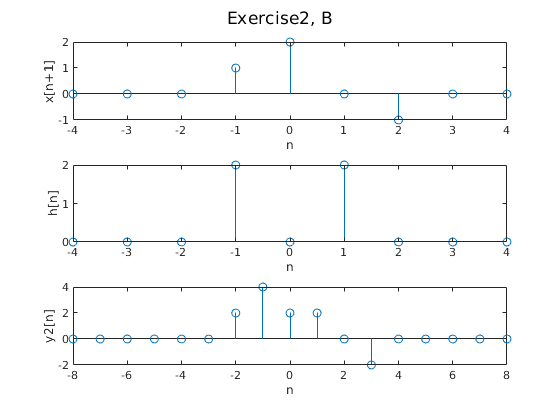

% Subpoint B
% Obtain the signal x[n] for the timespan defined in "t"
x_nplus1 = x_func(t+1);

y2 = conv(x_nplus1, h);

figure
sgtitle("Exercise2, B");
subplot(3,1,1); stem(t, x_nplus1); xlabel('n'); ylabel('x[n+1]');
subplot(3,1,2); stem(t, h); xlabel('n'); ylabel('h[n]');
subplot(3,1,3); stem(-8:8, y2); xlabel('n'); ylabel('y2[n]');

 Subpoint C

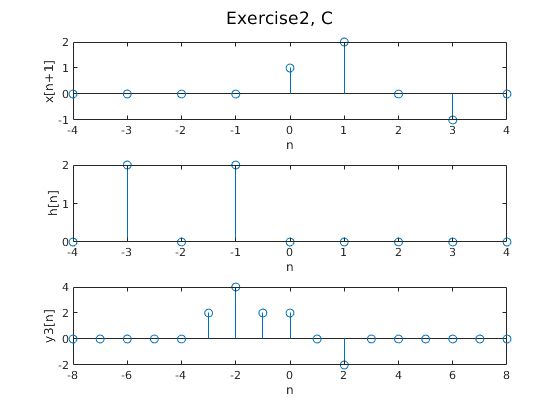

% Subpoint C
% Obtain the signal x[n] for the timespan defined in "t"
h_nplus2 = h_func(t+2);

y3 = conv(x, h_nplus2);

figure
sgtitle("Exercise2, C");
subplot(3,1,1); stem(t, x); xlabel('n'); ylabel('x[n+1]');
subplot(3,1,2); stem(t, h_nplus2); xlabel('n'); ylabel('h[n]');
subplot(3,1,3); stem(-8:8, y3); xlabel('n'); ylabel('y3[n]');

**Exercise 3**

Consider two discrete LTI systems S1 and S2, connected in series. The impulse response of S1 is $h_1 \left\lbrack n\right\rbrack =\alpha \;u\left\lbrack n\right\rbrack ,\left|\alpha \right|<1$and of S2 is $h_2 \left\lbrack n\right\rbrack =\sin \left(8n\right)$. Find the output of the system S for the input $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -\alpha \delta \left\lbrack n-1\right\rbrack$.

Represent graphically in Matlab all the signals and the system response.

The two systems, S1 and S2 are connected in series, so the output of system S1 will be considered to be the input for system S2.

The response of each of the systems to the input signal will be calculated as the convolution of the impulse response and the input signal.

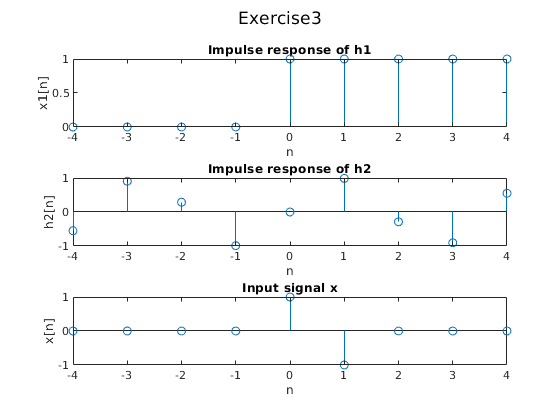

% Define the time interval
t_init = -4;
t_fin = 4;
t = t_init:1:t_fin;
% Define the unit step function
u = @(n) (n>=0);
alpha = 1;
% Define h1 and h2, the impulse response of the two systems
h1 = @(n) (min(max(alpha,-1),1).*u(t));
h2 = @(n) (sin(8*n));
% Define the input signal, x
x = @(n) (eq(n,0) - alpha*eq(n-1,0));

figure
sgtitle("Exercise3");
subplot(3,1,1); stem(t, h1(t)); xlabel('n'); ylabel('x1[n]');
title("Impulse response of h1");
subplot(3,1,2); stem(t, h2(t)); xlabel('n'); ylabel('h2[n]');
title("Impulse response of h2");
subplot(3,1,3); stem(t, x(t)); xlabel('n'); ylabel('x[n]');
title("Input signal x");

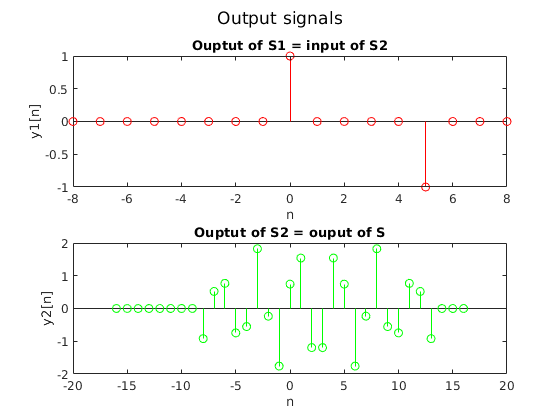


% Output of S1 is the input x, convolved with the impulse response of S1
% (i.e. h1[n]).
y1 = conv(x(t), h1(t));
figure
sgtitle("Output signals");
subplot(2,1,1); stem(2*t_init:2*t_fin, y1, "r"); xlabel('n'); ylabel('y1[n]');
title("Ouptut of S1 = input of S2");

y2 = conv(y1, h2(2*t_init:2*t_fin));
subplot(2,1,2); stem(4*t_init:4*t_fin, y2, "g"); xlabel('n'); ylabel('y2[n]');
title("Ouptut of S2 = ouput of S");